clc; 
clear;
syms x h a

%f = 4*x^2 - 2*x -4; % Source term
f = -1

f = -1

e = 10;
% No of Nodal points
nodes =e+1;

% numerical values for a, c, and h
a_num = 1;
% domain of X
x0 = 0;
xn = 1;

P = 3; % hermitie cubic shape Functions

phi_e = H_Cubic_beam_shapefunction_x(x0);

% Element length
h_num = (xn - x0) / e;

DOF_e =4

DOF_e = 4

%Degree of Freedom per element


% Local stiffness matrix
KNM_local = zeros(DOF_e, DOF_e, 'sym');
CNM_local = zeros(DOF_e, DOF_e, 'sym');


for N = 1:DOF_e
    for M = 1:DOF_e
        % Integrate to get the local stiffness matrix
        KNM_local(N, M) = int(a * diff(phi_e(N), x,2) * diff(phi_e(M), x,2),0,h_num);
        CNM_local(N, M) = int(phi_e(N) * phi_e(M), x, 0, h);
    end
end

% Display the local stiffness matrix
disp('Local Stiffness Matrix some element e:');

Local Stiffness Matrix some element e:


disp(KNM_local);

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{3} & \sigma_{1} & -\sigma_{3} & \sigma_{2}\\ \sigma_{1} & \frac{a\,\left(400\,h^{2}-60\,h+3\right)}{250\,h^{4}} & -\sigma_{1} & \sigma_{4}\\ -\sigma_{3} & -\sigma_{1} & \sigma_{3} & -\sigma_{2}\\ \sigma_{2} & \sigma_{4} & -\sigma_{2} & \frac{a\,\left(100\,h^{2}-30\,h+3\right)}{250\,h^{4}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,a\,\left(200\,h^{2}-35\,h+2\right)}{250\,h^{5}}\\ \sigma_{2}=\frac{3\,a\,\left(100\,h^{2}-25\,h+2\right)}{250\,h^{5}}\\ \sigma_{3}=\frac{6\,a\,\left(75\,h^{2}-15\,h+1\right)}{125\,h^{6}}\\ \sigma_{4}=\frac{a\,\left(200\,h^{2}-45\,h+3\right)}{250\,h^{4}} \end{array}$$



% Substitute values into the local  matrices
KNM_local_sub = double(subs(KNM_local, {a, h}, {a_num,h_num}));
CNM_local_sub = subs(CNM_local, h, h_num);

% Display the substituted local stiffness matrix
disp('Substituted values of a c and h in Local Stiffness Matrix:');

Substituted values of a c and h in Local Stiffness Matrix:


disp(KNM_local_sub);

       12000         600      -12000         600
         600          40        -600          20
      -12000        -600       12000        -600
         600          20        -600          40



disp('Substituted value h in Local C_NM Matrix:');

Substituted value h in Local C_NM Matrix:


disp(CNM_local_sub);

$$\left(\begin{array}{cccc} \frac{13}{350} & \frac{11}{21000} & \frac{9}{700} & -\frac{13}{42000}\\ \frac{11}{21000} & \frac{1}{105000} & \frac{13}{42000} & -\frac{1}{140000}\\ \frac{9}{700} & \frac{13}{42000} & \frac{13}{350} & -\frac{11}{21000}\\ -\frac{13}{42000} & -\frac{1}{140000} & -\frac{11}{21000} & \frac{1}{105000} \end{array}\right)$$





% Define degrees of freedom per node
DOF_e = 2;

% Total degrees of freedom
total_DOF = nodes * DOF_e;

% Initialize global stiffness matrix
K_global = zeros(total_DOF);
C_global = zeros(total_DOF);


% Assemble the global stiffness matrix
for i = 1:e
    % Global DOF indices for the current element
    start_index = (i-1) * DOF_e + 1;
    end_index = start_index + 2 * DOF_e - 1;

    % Assign local to global
    global_indices = start_index:end_index;
    K_global(global_indices, global_indices) = K_global(global_indices, global_indices) + KNM_local_sub;
    C_global(global_indices, global_indices) = C_global(global_indices, global_indices) + CNM_local_sub;
end

% Display the global stiffness matrix
disp('Global Stiffness Matrix:');

Global Stiffness Matrix:


disp(K_global);

       12000         600      -12000         600           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
         600          40        -600          20           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
      -12000        -600       24000           0      -12000         600           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
         600          20           0          80        -600          20           0           0           0           0           0           0           0           0           0           0           0 


disp('Global C Matrix:')

Global C Matrix:


disp(C_global);

    0.0371    0.0005    0.0129   -0.0003         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0005    0.0000    0.0003   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0129    0.0003    0.0743         0    0.0129   -0.0003         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0003   -0.0000         0    0.0000    0.0003   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0129    0.0003    0.0743         0    0.0129   -0.0003         0         0         0      

% Source vector Initialization 



% Source vector Initialization 
f_x = sym(zeros(nodes, 1));
% Calculate f(x) for each x value symbolically and store in the vector

X = x0:h_num:xn

X =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000



for i = 1:nodes
    f_x(i) = subs(f, x, X(i));
end
f_x = [f_x,f_x];

f_x = matrixToColumnVector(f_x);



Fv = double(C_global*f_x); %Fvector

K_global(1,:)= [1,zeros(1, total_DOF-1)];


K_global(end-1,:) = [zeros(1, total_DOF)];
K_global(end-1, end-1) = 1

K_global =            1           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
         600          40        -600          20           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
      -12000        -600       24000           0      -12000         600           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
         600          20           0          80        -600          20           0           0           0           0           0           0           0           0           0           0  




Fv(1) = 0;

Fv(end-1) = 0;


vv_global = zeros(total_DOF,1);
 


vv_global(total_DOF/2) = -1;


Gv = vv_global + Fv;

UVUV = K_global\Gv;

UV = columnVectorToMatrix(UVUV);

U = UV(:,1)

U =     0.0000
   -0.0103
   -0.0196
   -0.0271
   -0.0321
   -0.0339
   -0.0321
   -0.0271
   -0.0196
   -0.0103


V = UV(:,2)

V =    -0.1042
   -0.0993
   -0.0855
   -0.0637
   -0.0348
   -0.0000
    0.0348
    0.0637
    0.0855
    0.0993




myTable = table(X', U, V,'VariableNames', {'Nodal point', 'Deflection','slope'});
disp(myTable);

    Nodal point    Deflection        slope   
    ___________    ___________    ___________

          0         8.9338e-15       -0.10417
        0.1          -0.010254      -0.099333
        0.2          -0.019567        -0.0855
        0.3          -0.027087      -0.063667
        0.4          -0.032067      -0.034833
        0.5          -0.033854    -3.9683e-08
        0.6          -0.032067       0.034833
        0.7          -0.027087       0.063667
        0.8          -0.019567         0.0855
        0.9          -0.010254       0.099333
          1        -4.6282e-18        0.10417



disp("-------------------------------------------------------------")

-------------------------------------------------------------


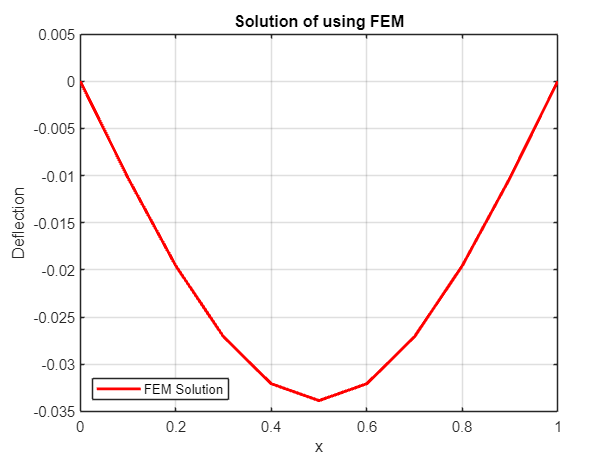


figure;
plot(X, U, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
xlabel("x");
ylabel("Deflection");
title("Solution of using FEM");
legend('Location', 'southwest');
grid on;

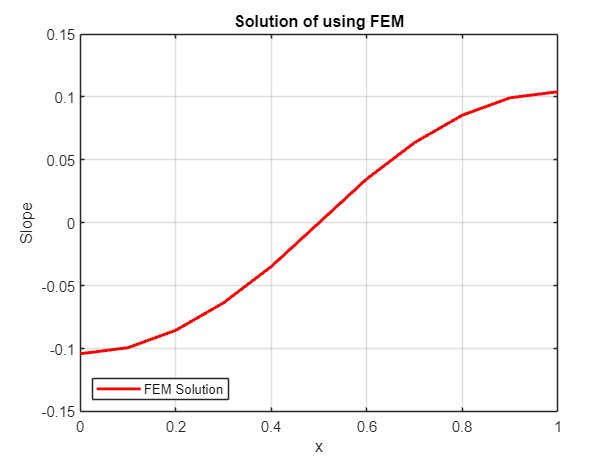


figure;
plot(X, V, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
xlabel("x");
ylabel("Slope");
title("Solution of using FEM");
legend('Location', 'southwest');
grid on;

function phi_e = H_Cubic_beam_shapefunction_x(x0)
    %Hermite cubic shape functions
    % Define symbolic variables
    syms x x1 h real;

    % in this formula x1 is starting point of the element

    % Define the Hermite cubic shape functions as provided
    N1 = 1 - (3*((x - x1)/h)^2) + (2*((x - x1)/h)^3);


    % for JN reddy N2 here assume inverted slope, So negative must be added for N2 and N4,
    % I'm following Dixit notation, ( Notes Only N2 and N4 are Different )

    N2 = (x - x1) * ((1-((x - x1)/h))^2);
    N3 = (3*((x - x1)/h)^2) - (2*((x - x1)/h)^3);
    N4 = (x - x1)*(((-((x - x1)/h)) + (((x - x1)/h)^2)));
    
    phi_e = sym(zeros(4,1));
    
    phi_e(1) = N1;
    phi_e(2) = N2;
    phi_e(3) = N3;
    phi_e(4) = N4;
    phi_e = subs(phi_e,x1,x0);

end
function B = matrixToColumnVector(A)
    % matrixToColumnVector converts a n x 2 matrix into a 2n x 1 column vector.

    % Check if the input matrix A has exactly 2 columns
    if size(A, 2) ~= 2
        error('Input matrix must have exactly 2 columns');
    end

    % Reshape the matrix A to a column vector
    B = reshape(A', [], 1);

    % Optionally, display the output vector
    % disp(B);  % Uncomment this line if you want to display the vector
end
function A = columnVectorToMatrix(B)
    % columnVectorToMatrix converts a 2n x 1 column vector into a n x 2 matrix.

    % Check if the length of vector B is even
    if mod(length(B), 2) ~= 0
        error('Length of input vector must be even');
    end

    % Calculate the number of rows for the matrix A
    numRows = length(B) / 2;

    % Reshape the vector B to a matrix A of size n x 2
    A = reshape(B, 2, numRows)';

    % Optionally, display the output matrix
    % disp(A);  % Uncomment this line if you want to display the matrix
end

